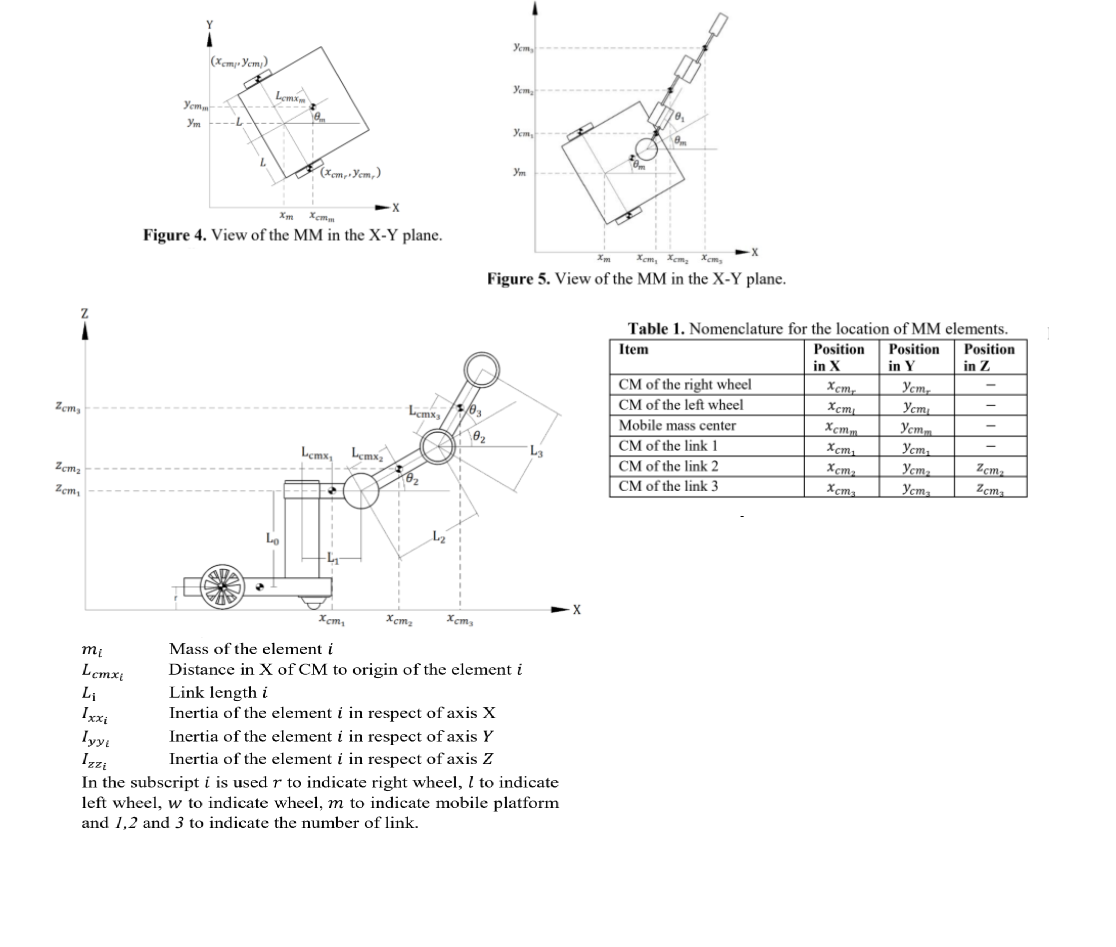

From equation (39) to (52) the positions of the bodies that make up the robot are presented; these equations are used to determine the kinetic and potential energy of the system.

clc; clearvars; close all;

%% Time + generalized coordinates
syms t real
syms x_m(t) y_m(t)
syms theta_m(t) theta_r(t) theta_l(t) theta_1(t) theta_2(t) theta_3(t)
%% Geometry (lengths, SI)
syms L d r L_0 L_1 L_2 L_cmx_m L_cmx_1 L_cmx_2 L_cmx_3 real
assumeAlso([L d r L_0 L_1 L_2 L_cmx_m L_cmx_1 L_cmx_2 L_cmx_3] > 0)

%% Trig shorthands
cm  = cos(theta_m(t));         sm  = sin(theta_m(t));
cm1 = cos(theta_m(t)+theta_1(t));  sm1 = sin(theta_m(t)+theta_1(t));
c2  = cos(theta_2(t));         s2  = sin(theta_2(t));
c23 = cos(theta_2(t)+theta_3(t));  s23 = sin(theta_2(t)+theta_3(t));


%% (39)–(52): positions
x_cm_r = x_m(t) + L*sm;                 y_cm_r = y_m(t) - L*cm;
x_cm_l = x_m(t) - L*sm;                 y_cm_l = y_m(t) + L*cm;

x_cm_m = x_m(t) + L_cmx_m*cm;           y_cm_m = y_m(t) + L_cmx_m*sm;

x_cm_1 = x_m(t) + d*cm + L_cmx_1*cm1;   y_cm_1 = y_m(t) + d*sm + L_cmx_1*sm1;

x_cm_2 = x_m(t) + d*cm + (L_1 + L_cmx_2*c2)*cm1;
y_cm_2 = y_m(t) + d*sm + (L_1 + L_cmx_2*c2)*sm1;
z_cm_2 = r + L_0 + L_cmx_2*s2;

x_cm_3 = x_m(t) + d*cm + (L_1 + L_2*c2 + L_cmx_3*c23)*cm1;
y_cm_3 = y_m(t) + d*sm + (L_1 + L_2*c2 + L_cmx_3*c23)*sm1;
z_cm_3 = r + L_0 + L_2*s2 + L_cmx_3*s23;

COM = struct( ...
 'x_cm_r',x_cm_r,'y_cm_r',y_cm_r,'x_cm_l',x_cm_l,'y_cm_l',y_cm_l, ...
 'x_cm_m',x_cm_m,'y_cm_m',y_cm_m, ...
 'x_cm_1',x_cm_1,'y_cm_1',y_cm_1, ...
 'x_cm_2',x_cm_2,'y_cm_2',y_cm_2,'z_cm_2',z_cm_2, ...
 'x_cm_3',x_cm_3,'y_cm_3',y_cm_3,'z_cm_3',z_cm_3);

%% Velocities via Jacobians
q  = [x_m; y_m; theta_m; theta_r; theta_l; theta_1; theta_2; theta_3];
qd = diff(q,t);

vel = @(p) jacobian(p,q)*qd;

v_cmr = vel([x_cm_r; y_cm_r]);
v_cml = vel([x_cm_l; y_cm_l]);
v_cmm = vel([x_cm_m; y_cm_m]);
v_cm1 = vel([x_cm_1; y_cm_1]);
v_cm2 = vel([x_cm_2; y_cm_2; z_cm_2]);
v_cm3 = vel([x_cm_3; y_cm_3; z_cm_3]);

%% Angular rates (useful for rotational KE)
%% Angular rates
w_m = diff(theta_m,t);   % base yaw
w_r = diff(theta_r,t);   % right wheel spin
w_l = diff(theta_l,t);   % left wheel spin

w1  = diff(theta_1,t);
w2  = diff(theta_2,t);
w3  = diff(theta_3,t);

% Components (simplified)
v_cm3 = simplify(v_cm3,'Steps',50);
v_cm3   % quick check

$$v\_cm3(t) = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}x_{m}\left(t\right)-\left(d\,\sin\left(\theta_{m}\left(t\right)\right)+\sin\left(\sigma_{1}\right)\,\sigma_{2}\right)\,\frac{\partial }{\partial t}\theta_{m}\left(t\right)-\cos\left(\sigma_{1}\right)\,\sigma_{3}\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)-\sin\left(\sigma_{1}\right)\,\sigma_{2}\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)-L_{\mathrm{cmx},3}\,\cos\left(\sigma_{1}\right)\,\sin\left(\sigma_{5}\right)\,\frac{\partial }{\partial t}\theta_{3}\left(t\right)\\ \left(d\,\cos\left(\theta_{m}\left(t\right)\right)+\cos\left(\sigma_{1}\right)\,\sigma_{2}\right)\,\frac{\partial }{\partial t}\theta_{m}\left(t\right)+\frac{\partial }{\partial t}y_{m}\left(t\right)-\sin\left(\sigma_{1}\right)\,\sigma_{3}\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)+\cos\left(\sigma_{1}\right)\,\sigma_{2}\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)-L_{\mathrm{cmx},3}\,\sin\left(\sigma_{5}\right)\,\sin\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}\theta_{3}\left(t\right)\\ \left(\cos\left(\sigma_{5}\right)\,L_{\mathrm{cmx},3}+\sigma_{4}\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)+L_{\mathrm{cmx},3}\,\cos\left(\sigma_{5}\right)\,\frac{\partial }{\partial t}\theta_{3}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\theta_{1}\left(t\right)+\theta_{m}\left(t\right)\\ \sigma_{2}=\cos\left(\sigma_{5}\right)\,L_{\mathrm{cmx},3}+\sigma_{4}+L_{1}\\ \sigma_{3}=\sin\left(\sigma_{5}\right)\,L_{\mathrm{cmx},3}+\sin\left(\theta_{2}\left(t\right)\right)\,L_{2}\\ \sigma_{4}=\cos\left(\theta_{2}\left(t\right)\right)\,L_{2}\\ \sigma_{5}=\theta_{2}\left(t\right)+\theta_{3}\left(t\right) \end{array}$$

%% ---------- Parameters for masses & inertias ----------
syms m_w m_m m1 m2 m3 real
syms I_yyw I_zzw I_m I_zz1 I_zz2 I_yy2 I_zz3 I_yy3 real  % principal inertias used in (67)–(72)
assumeAlso([m_w m_m m1 m2 m3 I_yyw I_zzw I_m I_zz1 I_zz2 I_yy2 I_zz3 I_yy3] > 0)

%% Handy speed-squared helpers (v'*v) for 2D/3D groups
speed2 = @(v) simplify(v.'*v, 'Steps', 50);

v2_cmr = speed2(v_cmr);          % right wheel CM (x,y)
v2_cml = speed2(v_cml);          % left  wheel CM (x,y)
v2_cmm = speed2(v_cmm);          % mobile platform CM (x,y)

v2_cm1 = speed2(v_cm1);          % link-1 CM (x,y)
v2_cm2 = speed2(v_cm2);          % link-2 CM (x,y,z)
v2_cm3 = speed2(v_cm3);          % link-3 CM (x,y,z)

%% Angular rates (already defined)
% w_m = diff(theta_m,t);  w1 = diff(theta_1,t);  w2 = diff(theta_2,t);  w3 = diff(theta_3,t);
% If you want wheel spin about z_w as in the paper, introduce theta_d(t) here:

%% ---------- Kinetic energies (67)–(72) ----------
% (67) Right wheel: translational + yaw about y_w + spin about z_w
K_r = 1/2*m_w*v2_cmr + 1/2*I_yyw*w_m^2 + 1/2*I_zzw*w_r^2;
% (68) Left wheel: same structure
K_l = 1/2*m_w*v2_cml + 1/2*I_yyw*w_m^2 + 1/2*I_zzw*w_l^2;

% (69) Mobile platform body: translational + yaw about its vertical
K_m = 1/2*m_m*v2_cmm + 1/2*I_m*w_m^2;

% (70) Link 1: translational + rotation about its joint axis z1 (theta_m + theta_1)
K_1 = 1/2*m1*v2_cm1 + 1/2*I_zz1*(w_m + w1)^2;

% (71) Link 2: translational + rotation about z2 plus pitch about y2
K_2 = 1/2*m2*v2_cm2 + 1/2*I_zz2*(w_m + w1)^2 + 1/2*I_yy2*w2^2;

% (72) Link 3: translational + rotation about z3 plus pitch about y3
K_3 = 1/2*m3*v2_cm3 + 1/2*I_zz3*(w_m + w1)^2 + 1/2*I_yy3*(w2 + w3)^2;

% Totals
K = simplify(K_r + K_l + K_m + K_1 + K_2 + K_3, 'Steps', 100);

%% ---------- Potential energies (73)–(77) ----------
syms g real
% As in the page you highlighted, only links that move in z get gravity contributions:
% U_r = U_l = U_m = U_1 = 0
U_r = sym(0); U_l = sym(0); U_m = sym(0); U_1 = sym(0);

% (76) U2 = -m2 g (L0 + L_cmx2 * s2)
U_2 = -m2*g*(L_0 + L_cmx_2*s2);

% (77) U3 = -m3 g (L0 + L2*s2 + L_cmx3*s23)
U_3 = -m3*g*(L_0 + L_2*s2 + L_cmx_3*s23);

U = simplify(U_r + U_l + U_m + U_1 + U_2 + U_3, 'Steps', 100);

%% ---------- Lagrangian ----------
Lagr = simplify(K - U, 'Steps', 100);
Lagr

%% ---------- Quick sanity checks ----------
% 1) Extract a component, e.g., y-velocity of link-1 CM (what you printed)
vy_cm1 = [0 1]*v_cm1;
vy_cm1

$$vy\_cm1(t) = \frac{\partial }{\partial t}y_{m}\left(t\right)+\left(\cos\left(\theta_{1}\left(t\right)+\theta_{m}\left(t\right)\right)\,L_{\mathrm{cmx},1}+\cos\left(\theta_{m}\left(t\right)\right)\,d\right)\,\frac{\partial }{\partial t}\theta_{m}\left(t\right)+L_{\mathrm{cmx},1}\,\cos\left(\theta_{1}\left(t\right)+\theta_{m}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)$$

% 2) Zero-angle static pose (all angles/vels = 0) -> potential reduces to constants
S0 = struct( ...
  'theta_m', 0, 'theta_1', 0, 'theta_2', 0, 'theta_3', 0, ...
  'x_m', 0, 'y_m', 0);
% Zero-pose substitution for sanity checks
Zsubs = @(expr) subs(expr, ...
 { theta_m(t),  theta_1(t),  theta_2(t),  theta_3(t), ...
   diff(theta_m(t),t), diff(theta_1(t),t), diff(theta_2(t),t), diff(theta_3(t),t), ...
   x_m(t), y_m(t), diff(x_m(t),t), diff(y_m(t),t) }, ...
 { 0,            0,           0,           0, ...
   0,            0,           0,           0, ...
   0,     0,     0,           0 });

K_at_rest = simplify(Zsubs(K))

$$K\_at\_rest(t) = 0.5000\,I_{\mathrm{zzw}}\,\left({\left(\frac{\partial }{\partial t}\theta_{l}\left(t\right)\right)}^{2}+{\left(\frac{\partial }{\partial t}\theta_{r}\left(t\right)\right)}^{2}\right)$$

U_at_rest = simplify(Zsubs(U))

$$U\_at\_rest = -L_{0}\,g\,\left(m_{3}+m_{2}\right)$$

%% Euler–Lagrange equations (unconstrained)
tau = simplify( diff(gradient(Lagr, qd), t) - gradient(Lagr, q), 'Steps', 50 )